clc
close all
clear

tr= stlread('part1.stl')

tr =   triangulation のプロパティ:

              Points: [4145×3 double]
    ConnectivityList: [8286×3 double]



figure
trimesh(tr)
axis('equal')
xlabel('x')
ylabel('y')
zlabel('z')
title('part1')

p=tr.Points

p =    -3.5000   58.6240  -80.2178
  -17.5000   59.8250  -78.2696
   -2.5000   58.0842  -79.2224
   -6.7559   58.0256  -77.8561
   -2.5000   57.4600  -77.9983
   -6.7559   57.2936  -76.7206
   -2.5000   56.6929  -76.8576
   -6.7559   56.4094  -75.7001
   -2.5000   56.2496  -76.3377
   -2.5000   55.8481  -75.9463



tr.Points(2,:)

ans =   -17.5000   59.8250  -78.2696


p(2,:)

ans =   -17.5000   59.8250  -78.2696


tr.Points(1,2)

ans = 58.6240

i=1

i = 1

j=2

j = 2

tr.Points(i,j)

ans = 58.6240


c=tr.ConnectivityList

c =      1     2     3
     3     2     4
     3     4     5
     5     4     6
     5     6     7
     7     6     8
     7     8     9
     9     8    10
    10     8    11
    10    11    12


c(2,:)

ans =      3     2     4



c1=c(2,1)

c1 = 3

p1=p(c1,:)

p1 =    -2.5000   58.0842  -79.2224



size(p,1)

ans = 4145


size(c,1)

ans = 8286


np=zeros(size(p))

np =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


i=1

i = 1

np(i,1)=p(i,1)+100

np =    96.5000         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


np(i,2)=p(i,2)+200

np =    96.5000  258.6240         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


np(i,3)=p(i,3)+300

np =    96.5000  258.6240  219.7822
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0



for i=1:size(p,1)
np(i,1)=p(i,1)+100;
np(i,2)=p(i,2)+200;
np(i,3)=p(i,3)+300;
end

tr2=triangulation(tr.ConnectivityList,np)

tr2 =   triangulation のプロパティ:

              Points: [4145×3 double]
    ConnectivityList: [8286×3 double]


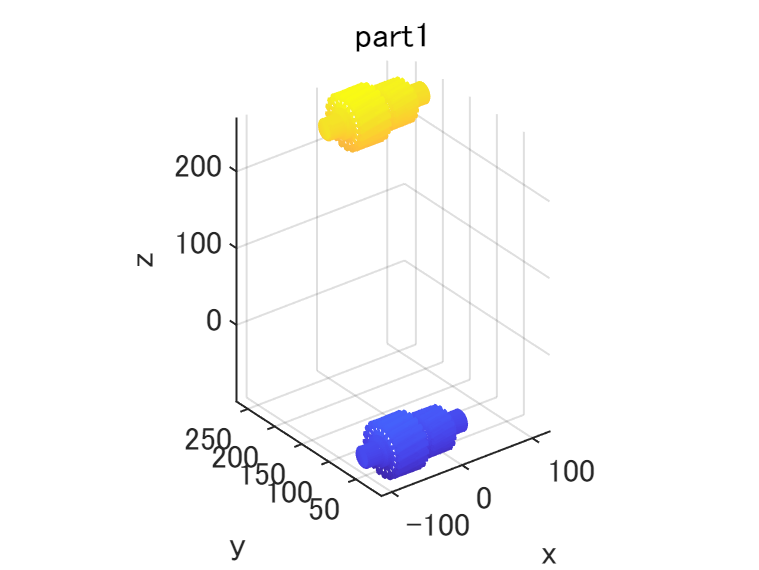


hold on
trimesh(tr2)